close all; clear; clc;

# STv4 TM motor with 2 batteries

**file name**: STv4_TM15d_20180928.mlx

**keywords:** 

**date of test:** 20180928

**file created by:** 20181001, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %[slugs/ft^3]
% If this wasn't recorded on the day of the test use 0.00228344448402635. 
% Record this in the notes section above

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data - continuous recording

This format assumes that the data output from RC Benchmark has not been changed

load('STv4_TM15d_20180928.mat');
time0 = STv4_TM15d_20180928(:,1);                       % [sec]
PWM0 = STv4_TM15d_20180928(:,2);                        % [micro sec]
Q0 = STv4_TM15d_20180928(:,4);                          % [ft.lbf]
T0 = STv4_TM15d_20180928(:,5);                          % [lbf]
Input_V0 = STv4_TM15d_20180928(:,6);                    % [Volts]
Input_A0 = STv4_TM15d_20180928(:,7);                    % [Amps]
rot_speed_rpm0 = STv4_TM15d_20180928(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad0 = rot_speed_rpm0 .* (pi/30);              % [rad/sec]
P_in_W0 = STv4_TM15d_20180928(:,9);                     % [Watts]
P_out_W0 = STv4_TM15d_20180928(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out0 = P_out_W0 .* 0.7478;                             % [ft.lbf/sec]         
P_in0 = P_in_W0 .* 0.7478;                               % [ft.lbf/sec]
Motor_Eff0 = STv4_TM15d_20180928(:,11);                 % [%]
Prop_Eff0 = STv4_TM15d_20180928(:,12);                  % [lbf/Watts]
Overall_Eff0 = STv4_TM15d_20180928(:,13);               % [lbf/Watts]  
ESC_Temp0 = STv4_TM15d_20180928(:,14);                  % [F]
Motor_Temp0 = STv4_TM15d_20180928(:,15);                % [F]

disk_loading0 = T0 ./ area;                     % [lb/sq.ft]

Settling_time0 = STv4_TM15d_20180928(:,17); % [s]
Max_Acc0 = STv4_TM15d_20180928(:,18);      % [RPM]

throttle0 = (PWM0 - 1000) ./ 10;

## Measured data - one point per step

load('STv4_1_TM15d_20180928.mat');
time1 = STv4_1_TM15d_20180928(:,1);                       % [sec]
PWM1 = STv4_1_TM15d_20180928(:,2);                        % [micro sec]
Q1 = STv4_1_TM15d_20180928(:,4);                          % [ft.lbf]
T1 = STv4_1_TM15d_20180928(:,5);                          % [lbf]
Input_V1 = STv4_1_TM15d_20180928(:,6);                    % [Volts]
Input_A1 = STv4_1_TM15d_20180928(:,7);                    % [Amps]
rot_speed_rpm1 = STv4_1_TM15d_20180928(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad1 = rot_speed_rpm1 .* (pi/30);              % [rad/sec]
P_in_W1 = STv4_1_TM15d_20180928(:,9);                     % [Watts]
P_out_W1 = STv4_1_TM15d_20180928(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out1 = P_out_W1 .* 0.7478;                             % [ft.lbf/sec]         
P_in1 = P_in_W1 .* 0.7478;                               % [ft.lbf/sec]
Motor_Eff1 = STv4_1_TM15d_20180928(:,11);                 % [%]
Prop_Eff1 = STv4_1_TM15d_20180928(:,12);                  % [lbf/Watts]
Overall_Eff1 = STv4_1_TM15d_20180928(:,13);               % [lbf/Watts]  
ESC_Temp1 = STv4_1_TM15d_20180928(:,14);                  % [F]
Motor_Temp1 = STv4_1_TM15d_20180928(:,15);                % [F]

disk_loading1 = T1 ./ area;                     % [lb/sq.ft]

Settling_time1 = STv4_1_TM15d_20180928(:,17); % [s]
Max_Acc1 = STv4_1_TM15d_20180928(:,18);      % [RPM]

throttle1 = (PWM1 - 1000) ./ 10;

## Thrust, Power, and Torque Coefficents 0

C_T0 = T0 ./ (p .* area * (rot_speed_rad0 * radius).^2);
C_P0 = P_out0 ./ (p .* area .* (rot_speed_rad0 .* radius).^3);
C_Q0 = Q0 ./ (p .* area .* (rot_speed_rad0 .* radius).^(2) .* radius);


## Thrust, Power, and Torque Coefficents 1

C_T1 = T1 ./ (p .* area * (rot_speed_rad1 * radius).^2);
C_P1 = P_out1 ./ (p .* area .* (rot_speed_rad1 .* radius).^3);
C_Q1 = Q1 ./ (p .* area .* (rot_speed_rad1 .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

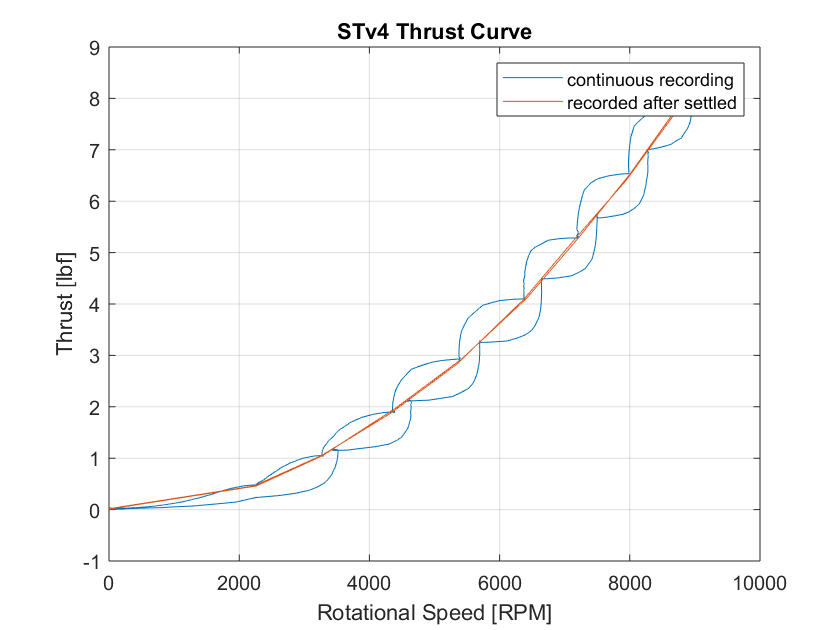

figure(1)
plot(rot_speed_rpm0, T0, rot_speed_rpm1, T1); title('STv4 Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');
legend('continuous recording', 'recorded after settled')

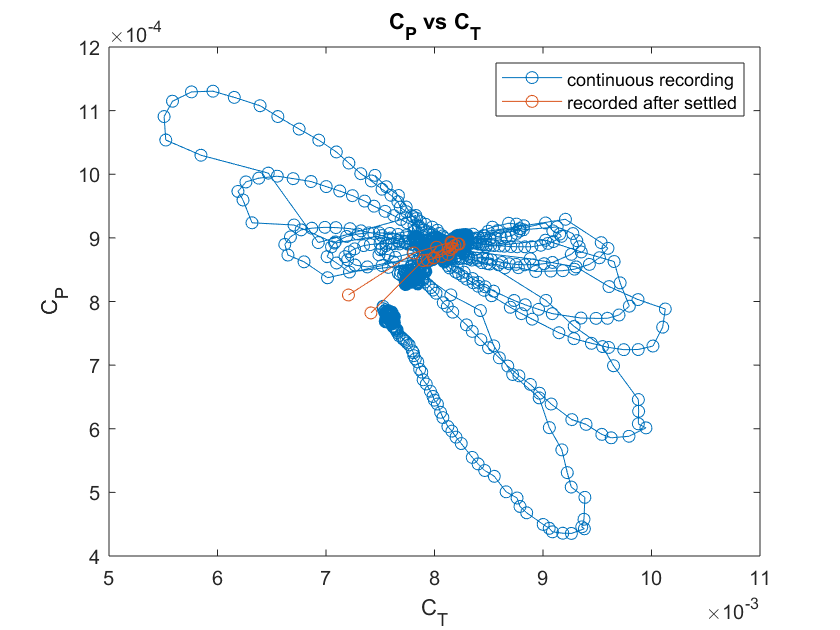


figure(2)
plot(C_T0(324:1798), C_P0(324:1798),'o-', C_T1, C_P1, 'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')
legend('continuous recording', 'recorded after settled')

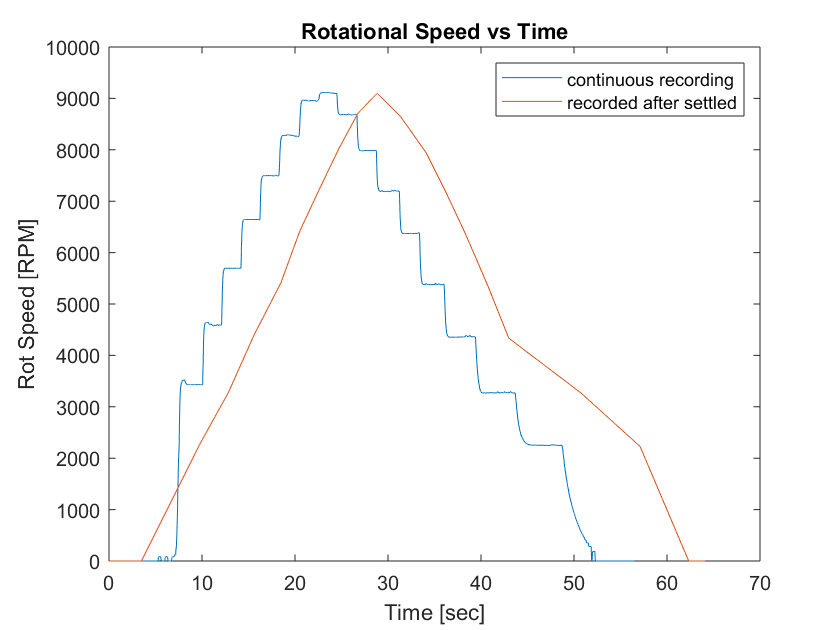


figure(3)
plot(time0, rot_speed_rpm0, time1, rot_speed_rpm1); title('Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')
legend('continuous recording', 'recorded after settled');

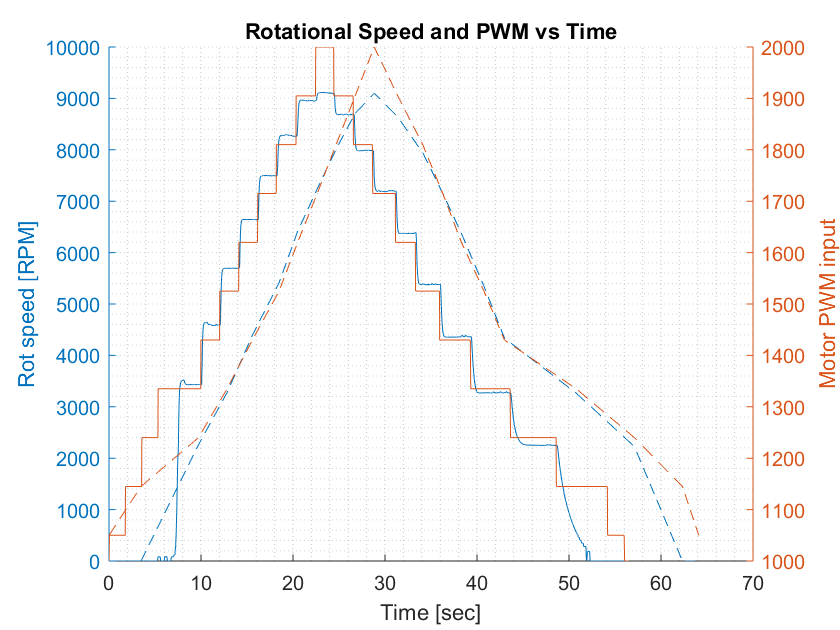


figure(4)
hold on
yyaxis left
plot(time0, rot_speed_rpm0, time1, rot_speed_rpm1);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time0, PWM0, time1, PWM1);
ylabel('Motor PWM input');
title('Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

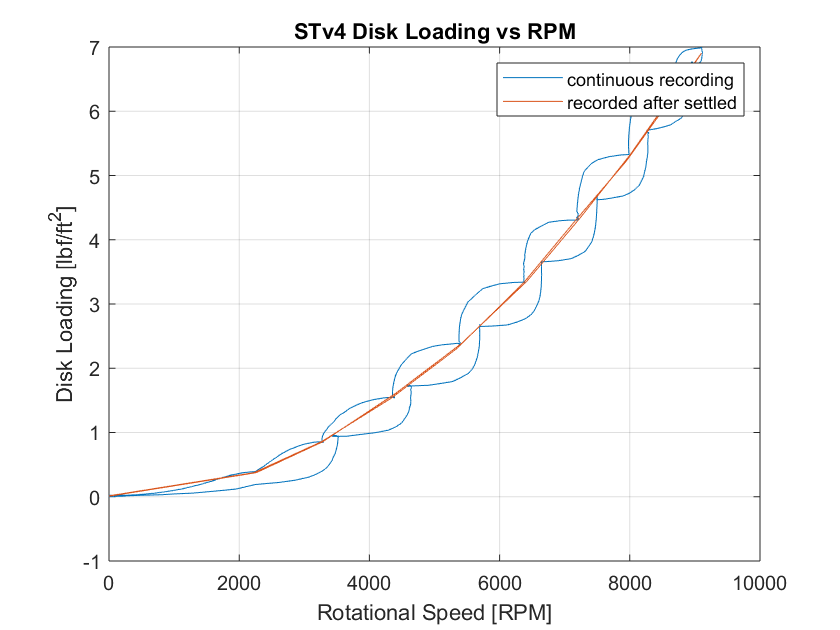

%legend('continuous recording', 'recorded after settled');

figure(5)
plot(rot_speed_rpm0, disk_loading0, rot_speed_rpm1, disk_loading1); title('STv4 Disk Loading vs RPM');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')
grid('on'); legend('continuous recording', 'recorded after settled');

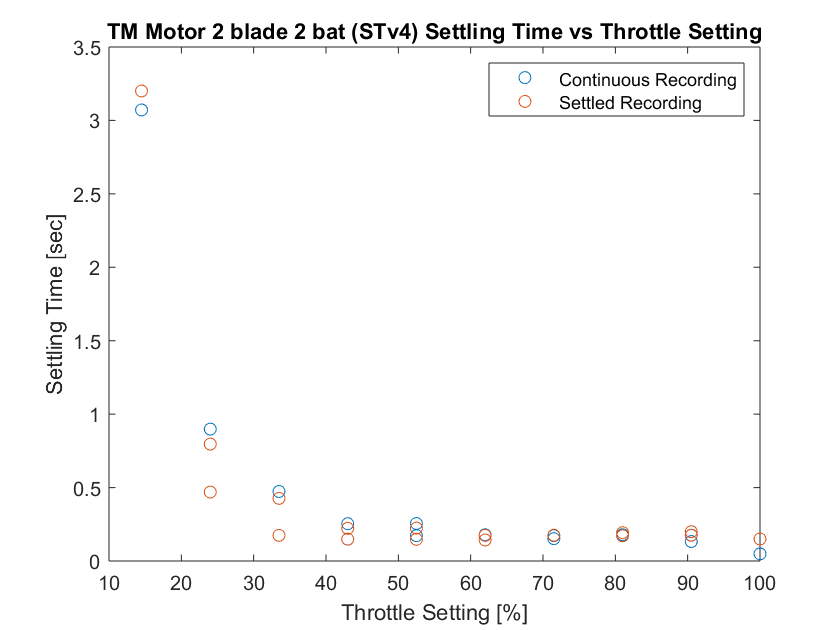


figure(6)
plot(throttle0, Settling_time0, 'o',throttle1, Settling_time1, 'o');
title('TM Motor 2 blade 2 bat (STv4) Settling Time vs Throttle Setting');
ylabel('Settling Time [sec]'); xlabel('Throttle Setting [%]');
legend('Continuous Recording', 'Settled Recording');

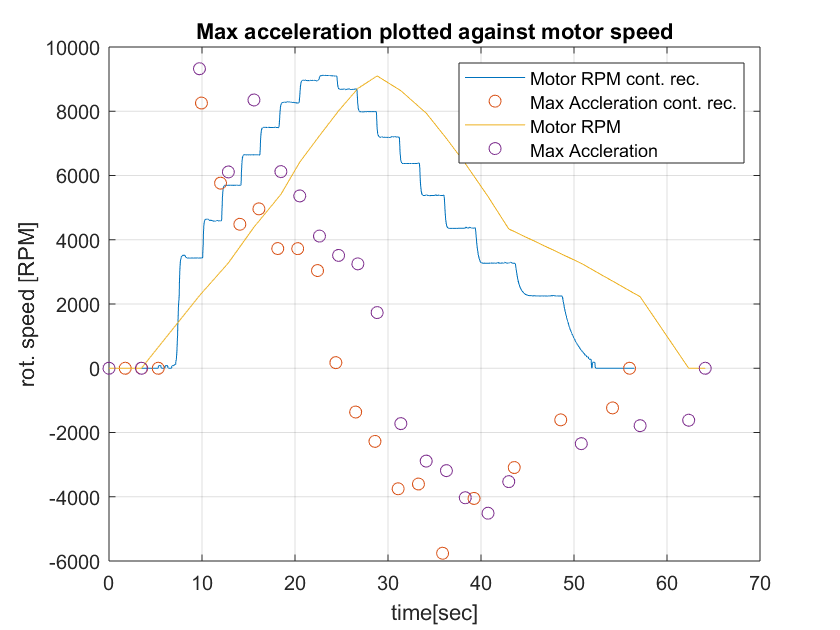


figure(7)
plot(time0, rot_speed_rpm0, time0, Max_Acc0, 'o', time1, rot_speed_rpm1, time1, Max_Acc1, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM cont. rec.', 'Max Accleration cont. rec.', 'Motor RPM', 'Max Accleration'); 
grid('on');

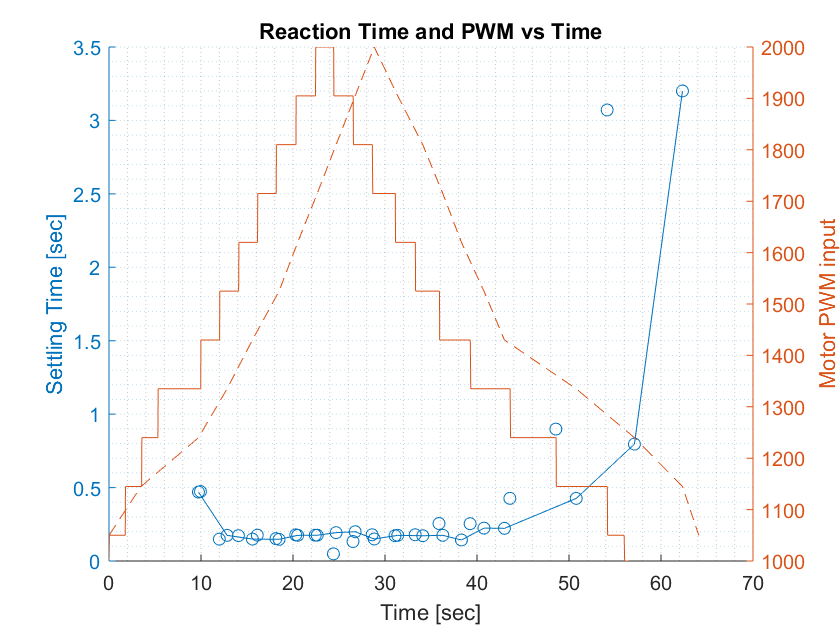


figure(8)
hold on
yyaxis left
plot(time0,Settling_time0, 'o-', time1,Settling_time1, 'o-');
ylabel('Settling Time [sec]');
yyaxis right
plot(time0, PWM0, time1, PWM1);
ylabel('Motor PWM input');
title('Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

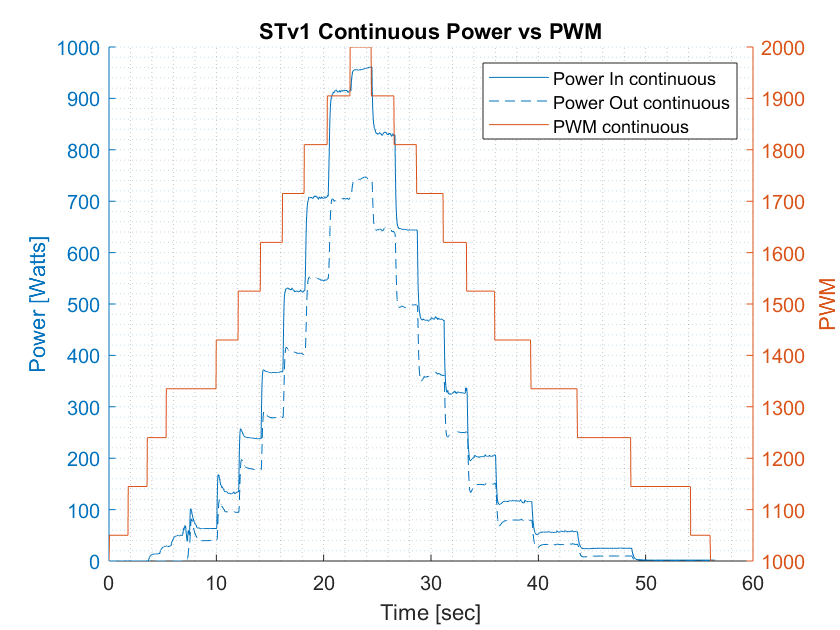


figure(9)
hold on
yyaxis left
plot(time0, P_in_W0, time0, P_out_W0);
ylabel('Power [Watts]');
legend('Power In continuous', 'Power Out continuous');
yyaxis right
plot(time0, PWM0, 'DisplayName','PWM continuous');
ylabel('PWM');
title('STv1 Continuous Power vs PWM');
xlabel('Time [sec]');
grid('minor');
hold off

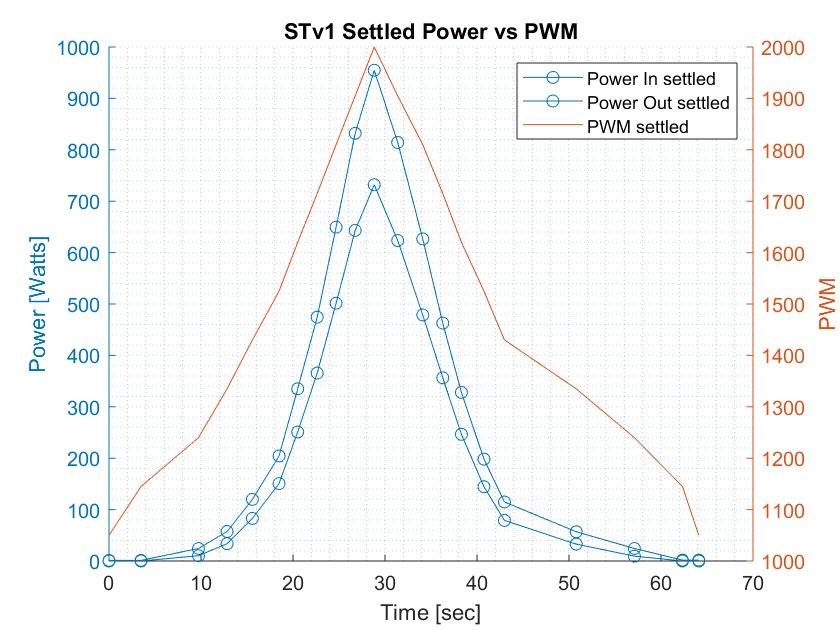


figure(10)
hold on
yyaxis left
plot(time1, P_in_W1, 'o-', time1, P_out_W1, 'o-');
ylabel('Power [Watts]');
legend('Power In settled', 'Power Out settled');
yyaxis right
plot(time1, PWM1, 'DisplayName','PWM settled');
ylabel('PWM');
title('STv1 Settled Power vs PWM');
xlabel('Time [sec]');
grid('minor');
hold off

## Comparing Data to Momentum Theory

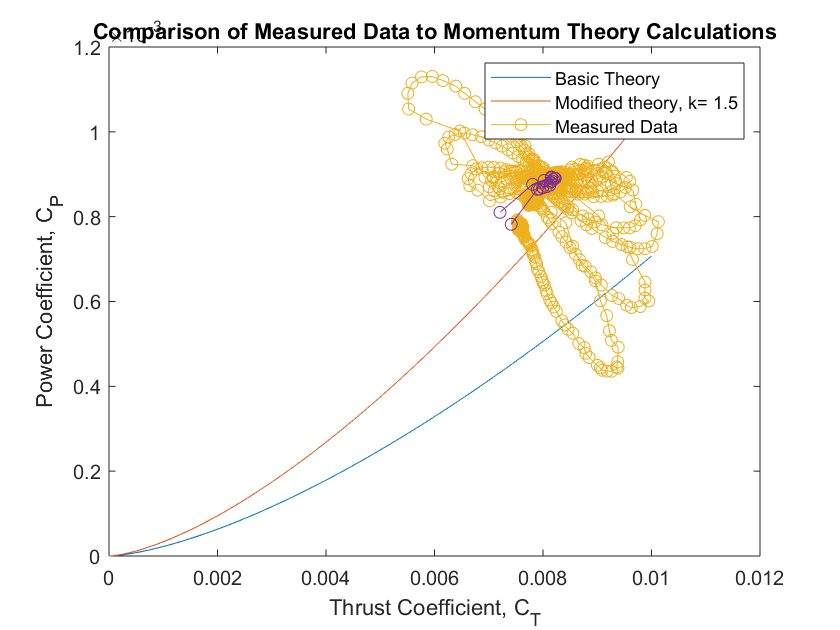

k = 1.5;
C_T_theory = linspace(0, 0.01, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T0(324:1798), C_P0(324:1798), 'o-', C_T1, C_P1, 'o-');
title('Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.5', 'Measured Data')